Generate an array of 100 elements and save it in the variable ***x***

t = linspace(-pi,pi,100);
rng default  %initialize random number generator
x = sin(t) + 0.25*rand(size(t));

Use FIR filter

windowSize = 10;
y1b = (1/windowSize)*ones(1,windowSize);
y1a = 1;
y1 = filter(y1b,y1a,x);

Use IIR filter

y2b = 0.1;
y2a = [1 -0.9];
y2 = filter(y2b,y2a,x);

Plot graphs

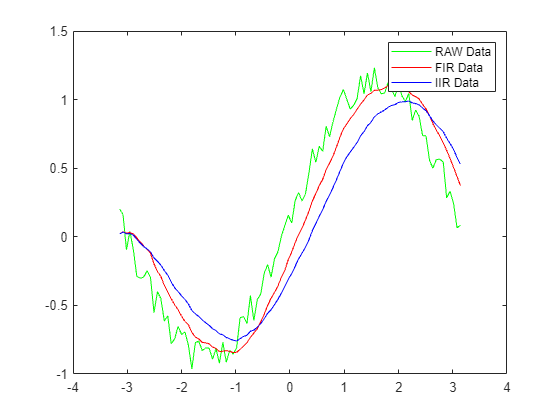

plot(t,x,"g")
hold on
plot(t,y1,"r")
plot(t,y2,"b")
legend('RAW Data','FIR Data', "IIR Data")